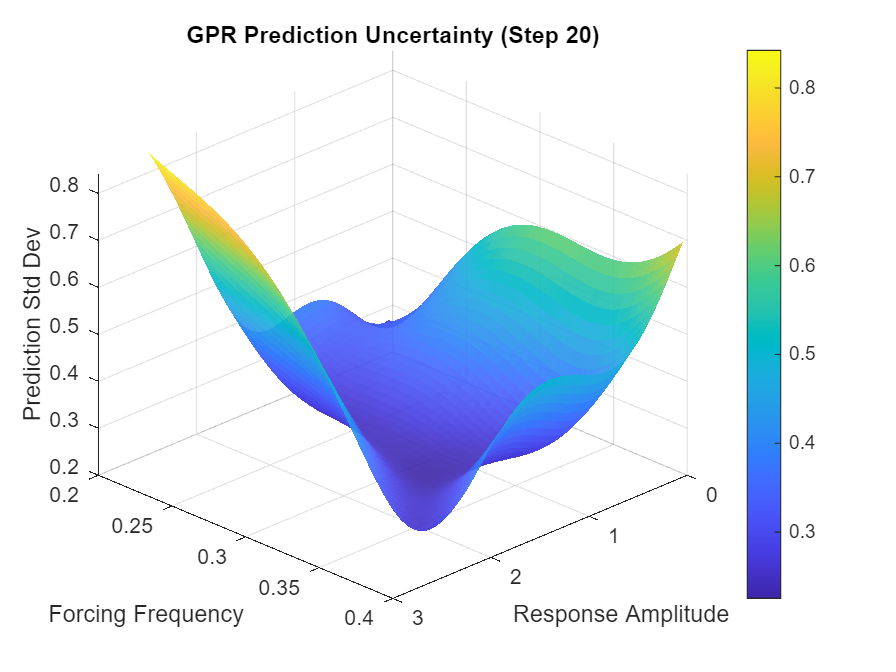

%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]

forcing_amp   = data(:, 1);  % dependent variable
forcing_freq  = data(:, 2);  % input
response_amp  = data(:, 3);  % input

%% Initial Training Subset (random small sample)
n_init = 5;
idx_train = randperm(size(data, 1), n_init);

X_train = data(idx_train, [3, 2]);  % [response_amp, forcing_freq]
Y_train = data(idx_train, 1);      % forcing_amp

%% Prediction Grid
resp_range = linspace(min(response_amp), max(response_amp), 50);
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
[RR, FF] = meshgrid(resp_range, freq_range);  % Grid for prediction
X_query = [RR(:), FF(:)];

%% Iterative Training
n_iter = 20;  % Number of new points to add iteratively

for step = 1:n_iter
    % Train model
    gpr_model = fitrgp(X_train, Y_train, ...
        'KernelFunction', 'squaredexponential', ...
        'Standardize', true);

    % Predict output and confidence
    [Y_pred, Y_std] = predict(gpr_model, X_query);
    AA = reshape(Y_pred, size(RR));     % Forcing amp surface
    STD = reshape(Y_std, size(RR));     % Confidence surface

    % Plot prediction surface
    figure(1); clf;
    surf(FF, AA, RR, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
    hold on;
    scatter3(forcing_freq, forcing_amp, response_amp, 10, 'k', 'filled');
    scatter3(X_train(:, 2), Y_train, X_train(:, 1), 40, 'r', 'filled');
    xlabel('Forcing Frequency'); ylabel('Forcing Amplitude'); zlabel('Response Amplitude');
    title(['GPR Prediction (Step ', num2str(step), ')']);
    view(135, 30); grid on; drawnow;

    % Plot confidence surface
    figure(2); clf;
    surf(RR, FF, STD, 'EdgeColor', 'none', 'FaceAlpha', 0.9);
    xlabel('Response Amplitude'); ylabel('Forcing Frequency'); zlabel('Prediction Std Dev');
    title(['GPR Prediction Uncertainty (Step ', num2str(step), ')']);
    colorbar; view(135, 30); grid on; drawnow;

    % === Select new point with max uncertainty ===
    [~, max_idx] = max(Y_std);
    new_x = X_query(max_idx, :);  % [resp_amp, freq]
    
    % Find closest point in full dataset to that location
    [~, closest_idx] = min(vecnorm(data(:, [3, 2]) - new_x, 2, 2));
    
    % Append to training set if not already in it
    if ~ismember(closest_idx, idx_train)
        idx_train(end+1) = closest_idx;
        X_train = [X_train; data(closest_idx, [3, 2])];
        Y_train = [Y_train; data(closest_idx, 1)];
    end
end